# Filtros

## Importar datos

Importar "S9....mat" de Utils4SP

%Cambiar la ruta según su repositorio
load("../../Utils4SP/Datasets/S9_Filtros.mat")


%Preproc
atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"])=fillmissing(atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"]),"linear");

T1=datetime(2021,05,20);
T2=datetime(2021,05,24);
index=atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;
atmosfera=atmosfera(index,:);

%Insertar campo de dia y noche
dateTime_Hours=hour(atmosfera.DateTime);
day_night=discretize(dateTime_Hours,[0 8 18 24],'categorical',["Noche" "Dia" "Noche"]);
atmosfera.dayNight=day_night;

## Promedio móvil

- Aplicar promedio móvil a todos los campos de atmósfera

- Comparar series de tiempo antes y después

- Comparar el contenido espectral antes y después del filtro

- Hacer un chart de dispersión y hacer nuevamente un ajuste. Comparar la calidad del ajuste respecto a la práctica de S5.

%Promedio móvil 
atmos_movMean_3=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},3);
atmos_movMean_100=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},100);
atmos_movMean_1000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},1000);
atmos_movMean_10000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},10000);

%Visualizar temperatura sin filtro y con filtro
figure
plot(atmosfera.DateTime,[ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],'LineWidth',2)
xlim([T1 T2])
legend("Original","Orden 3","Orden 100","Orden 1000" )
ylabel("Temperatura °C")
title("Temperatura en mi casa")
grid on

%Contenido espectral
N=numel(atmosfera.Temp_C);
[Pxx,f]=periodogram([ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],flattopwin(N),N*10,1/5);

%Visualización de contenido espectral
figure
plot(f,pow2db(Pxx))
legend("Original","Orden 3","Orden 100","Orden 1000" )
title("Contenido espectral de la temperatura")
ylabel("PSD dB")
xlabel("Frecuencia [Hz]")
grid on


El fenómeno a lo largo de varios días es complejo. Son muchas las variables las que actúan sobre el sistema. Suponer una buena correlación entre la humedad y la temperatura en un tramo grande de tiempo es una aproximación incorrecta. Si bien hay inidicios de que hay una relación, no son lo suficientemente fuertes como para aseverar que siempre será así. Para discriminar un poco más los datos, se separaron en conjuntos de día y de noche, además de discriminarlas por día calendario.

figure
gscatter(atmosfera.Temp_C,atmosfera.Hum_perc,atmosfera.dayNight,[],'.')
title("Discriminación por día y por noche")
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")

index=atmosfera.dayNight=="Dia";
figure
gscatter(atmosfera.Temp_C(index),atmosfera.Hum_perc(index),day(atmosfera.DateTime(index)),[],'.')
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")
title("Discriminación por fecha (Día)")

index=atmosfera.dayNight=="Noche";
figure
gscatter(atmosfera.Temp_C(index),atmosfera.Hum_perc(index),day(atmosfera.DateTime(index)),[],'.')
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")
title("Discriminación por fecha (Noche)")


Por el bien del ejercicio, únicamente tomaremos un suconjunto bien comportado de un solo día durante el calentamiento atmosférico.

atmosfera_index=atmosfera.DateTime>datetime(2021,05,23,8,0,0) &...
    atmosfera.DateTime<datetime(2021,05,23,18,0,0);

atmosfera_sub=atmosfera(atmosfera_index,:);
%Ajuste
[fit_line_nofil,gof_nofil]=fit(atmosfera_sub.Temp_C,atmosfera_sub.Hum_perc,'poly2')

fit_line_nofil =      Linear model Poly2:
     fit_line_nofil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      0.0482  (0.04668, 0.04973)
       p2 =      -5.156  (-5.241, -5.071)
       p3 =         146  (144.9, 147.1)

gof_nofil = struct with fields:
           sse: 2.1741e+04
       rsquare: 0.9833
           dfe: 7156
    adjrsquare: 0.9833
          rmse: 1.7430


[fit_line_fil,gof_fil]=fit(atmos_movMean_1000(atmosfera_index,2),atmos_movMean_1000(atmosfera_index,3),'poly2')

fit_line_fil =      Linear model Poly2:
     fit_line_fil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.02454  (0.02376, 0.02531)
       p2 =      -3.931  (-3.974, -3.889)
       p3 =       131.2  (130.6, 131.8)

gof_fil = struct with fields:
           sse: 3.8385e+03
       rsquare: 0.9970
           dfe: 7156
    adjrsquare: 0.9970
          rmse: 0.7324


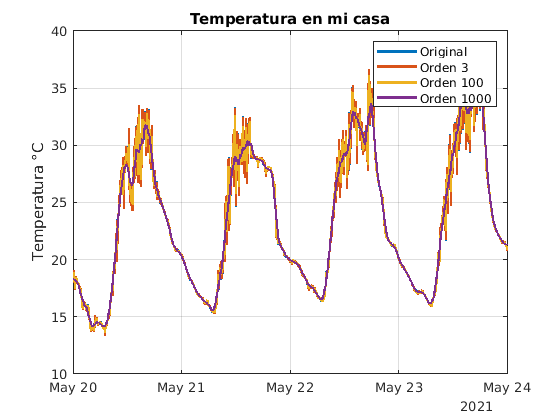

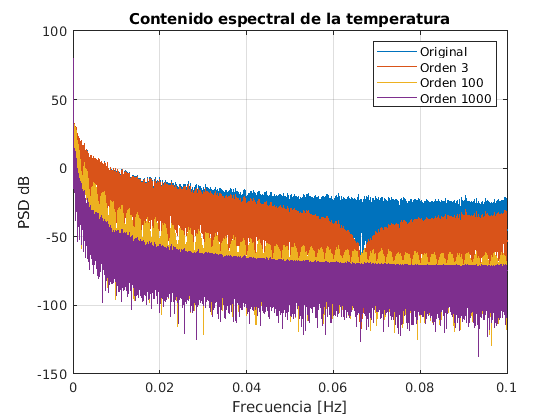

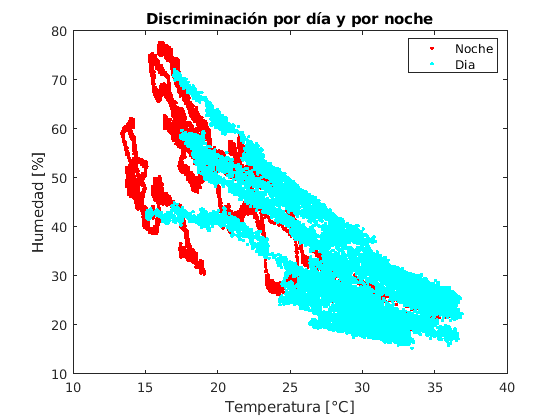

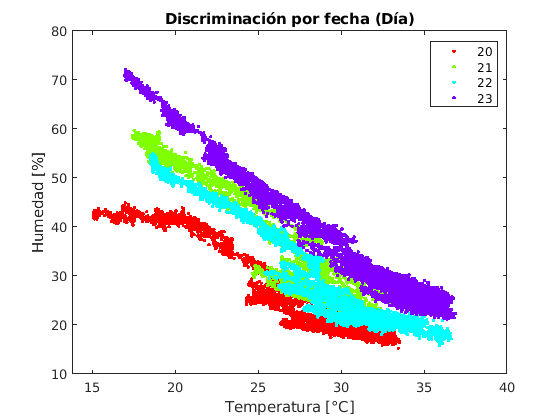

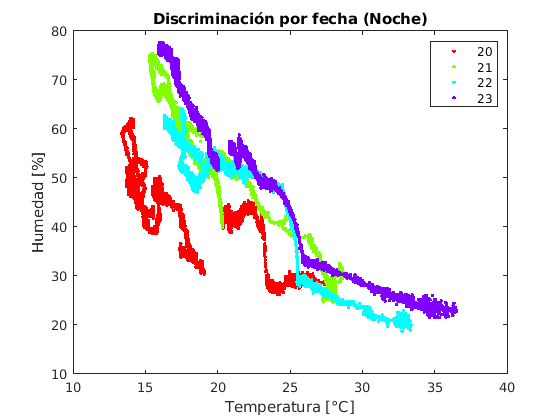

%Dispersión filtrada Hum vs temp
figure
%Original
scatter(atmosfera_sub.Temp_C,atmosfera_sub.Hum_perc,'Marker','.')
hold on

%Filtro orden 1000
scatter(atmos_movMean_1000(atmosfera_index,2),atmos_movMean_1000(atmosfera_index,3),'Marker','.')
plot(fit_line_nofil,'--r')
plot(fit_line_fil,'-.g')

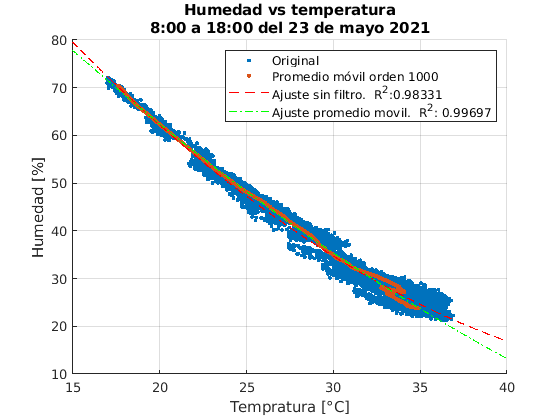

hold off
xlabel("Tempratura [°C]")
ylabel("Humedad [%]")
grid on
title(["Humedad vs temperatura";"8:00 a 18:00 del 23 de mayo 2021"])
legend("Original","Promedio móvil orden 1000","Ajuste sin filtro.  R^2:"+gof_nofil.adjrsquare,"Ajuste promedio movil.  R^2: "+gof_fil.adjrsquare)

## Detrend

Hacer detrend a las componentes x & y del campo magnético de Cassini con las siguientes técnicas:

- Restando promedio móvil

- Ajustando un polinomio

- Usando detrend


v_muestras=1:numel(Cassini.Bx_nT);
%Promedio movil y polinomio
cassini_movmean=movmean(Cassini{:,["Bx_nT" "By_nt"]},100);
fit_cassini=fit(v_muestras',Cassini.Bx_nT,'poly5');


%Detend (restar promedio movil y polinomio)
cassini_detrend_movmean=Cassini.Bx_nT-cassini_movmean(:,1);
cassini_detrend_poly=Cassini.Bx_nT-fit_cassini(v_muestras);
%Detrend por la función "detrend"
cassini_detrend_detrend=detrend(Cassini.Bx_nT,5);

Aplicar el espectrograma a la magnitud de Cassini antes y después del detrend. Observar por qué es importante quitar las bajas frecuencias (Incluido el DC).

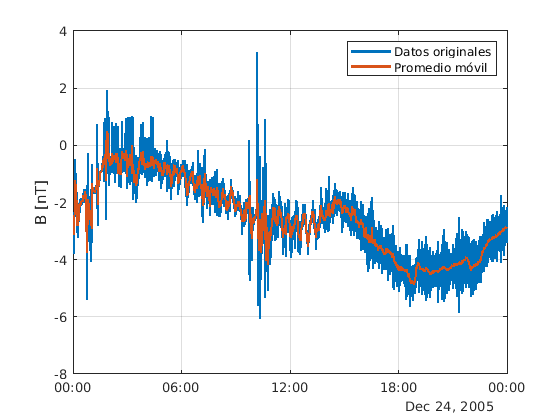

%Visualizacion de datos originales y promedio movil
figure
plot(Cassini.FechaHora,[Cassini.Bx_nT cassini_movmean(:,1) ],'LineWidth',2)
legend("Datos originales","Promedio móvil")
ylabel("B [nT]")
grid on

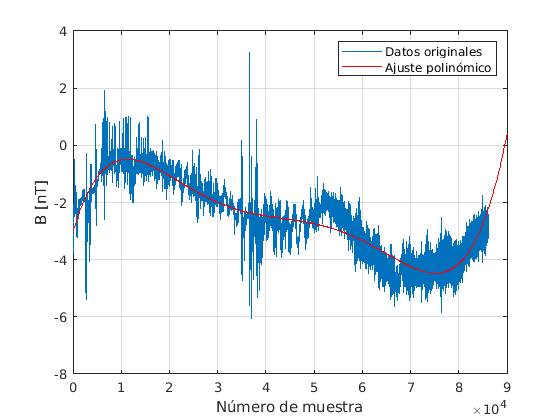


%Visualización de datos y ajuste polinomial
figure
plot(Cassini.Bx_nT)
hold on
plot(fit_cassini)
hold off
ylabel("B [nT]")
legend("Datos originales","Ajuste polinómico")
xlabel("Número de muestra")
grid on

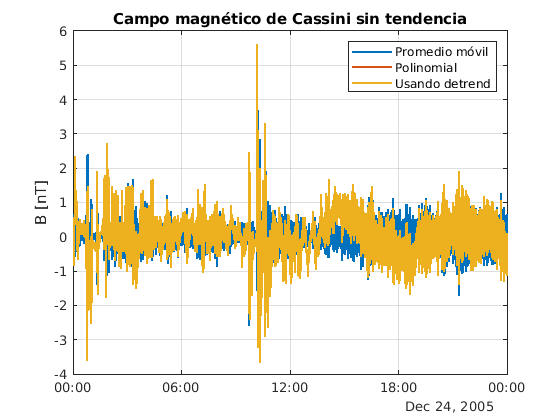


%Visualizacion de señales sin tendencia en tiempo
figure
plot(Cassini.FechaHora,[cassini_detrend_movmean cassini_detrend_poly cassini_detrend_detrend],'LineWidth',1.5)
legend("Promedio móvil","Polinomial","Usando detrend")
grid on
ylabel("B [nT]")
title("Campo magnético de Cassini sin tendencia")

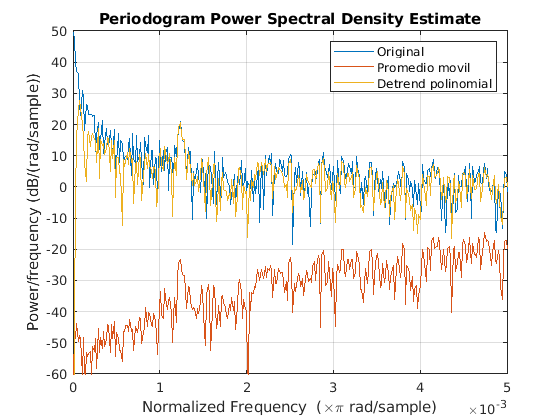


%Visualizacion en frecuencia
figure
periodogram([Cassini.Bx_nT cassini_detrend_movmean cassini_detrend_detrend])
legend("Original","Promedio movil","Detrend polinomial")
xlim([0 0.005])
ylim([-60 50])

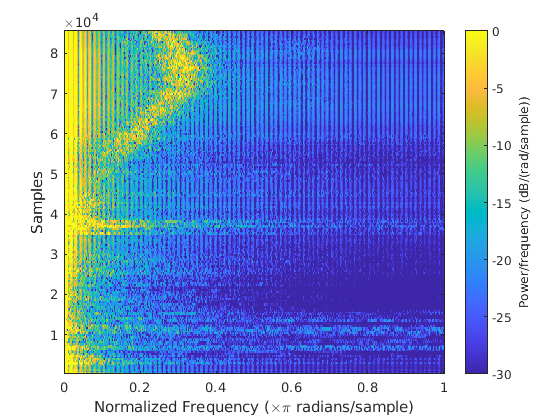


N_spectr=round(numel(Cassini.Bx_nT)/100);
%Espectrograma de señal original y de señal detrended
figure
spectrogram(Cassini.Bx_nT,rectwin(N_spectr),[],[])
caxis([-30 0])

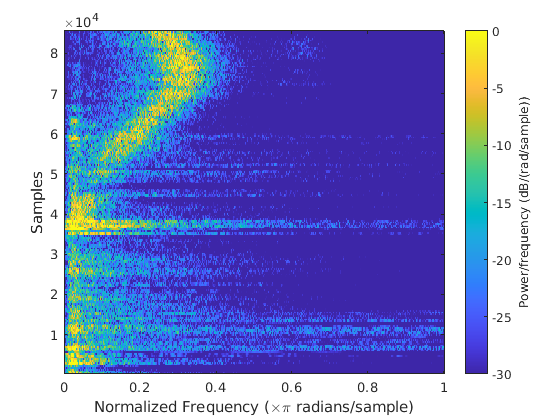

% %señal detrended
figure
spectrogram(cassini_detrend_movmean,rectwin(N_spectr),[],[])
caxis([-30 0])

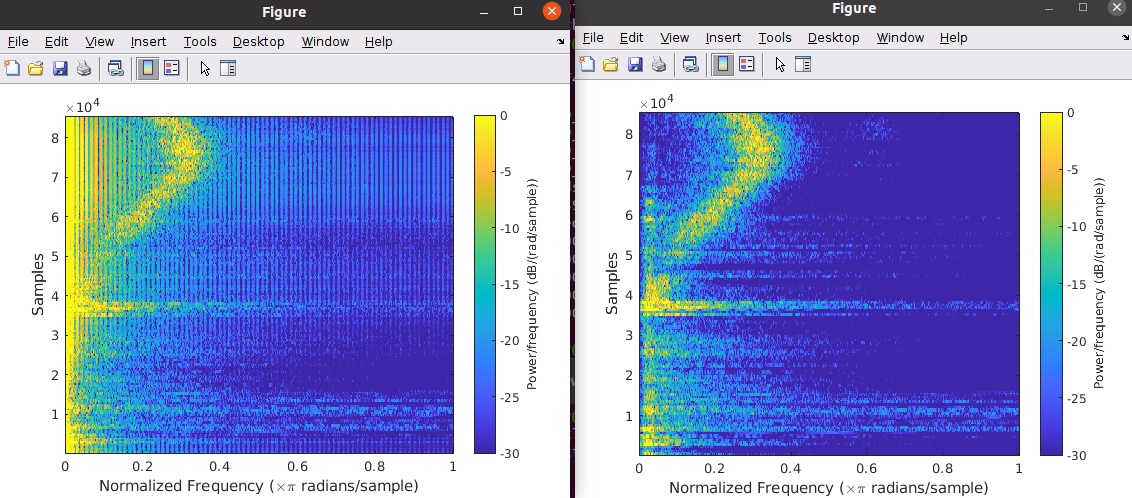

Izquierda: Derrame espectral por la señal DC// Derecha: Sin derrame

## Espectrograma vs paper

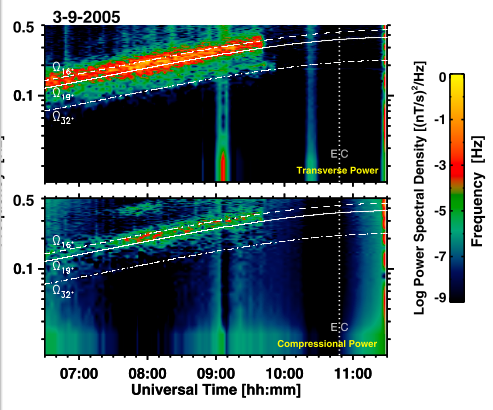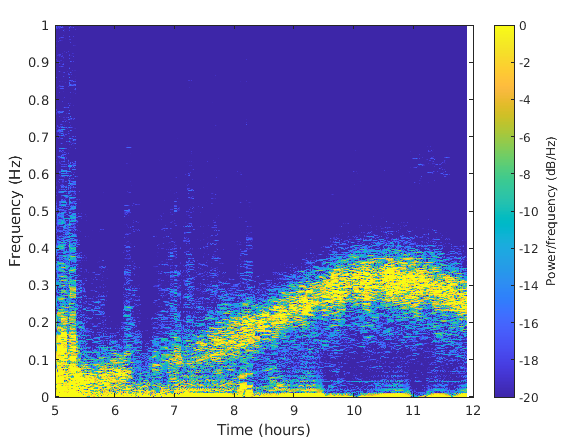

Izquierda: Paper de Rodriguez et. al. sobre onda ion ciclotrónicas encontradas por Cassini // Derecha: Espectrograma de los datos de Cassini correspondientes a esa fecha

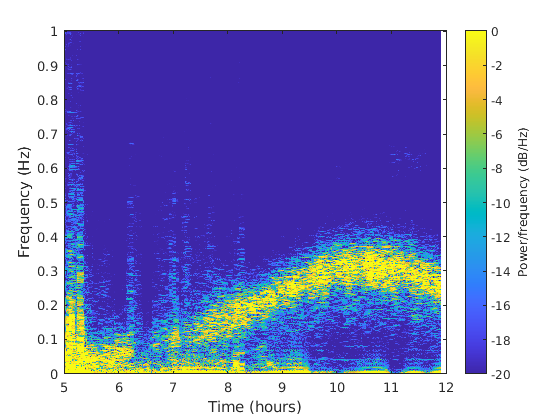

%Espectrograma limpio
figure
spectrogram(cassini_detrend_detrend,rectwin(N_spectr),N_spectr-1,[],2,'Yaxis')
caxis([-20 0])
xlim([5 12])

## No lineales

Contexto: Los datos de RVB son producto de un sensor altamente inestable y ruidoso.

Hacer la reconstrucción facial de los datos de RVB:

- Remover NaN's

- Usar un filtro no lineal para quitar la mayor cantidad de ruido

- Usar promedio móvil para dar el toque final

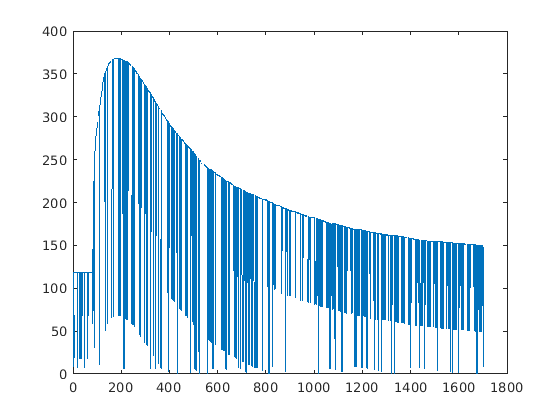

%Visualizar datos originales
figure
plot(RVB_data)


%Revisar si hay nans
sum(ismissing(RVB_data))

ans = 57


%Remover nans por interpolación
RVB_data_Nans=fillmissing(RVB_data,'movmean',10);

%Corroborar
sum(ismissing(RVB_data_Nans))

ans = 0

Usar Máximo móvil para eliminar los saltos. Elegí este filtro porque funciona, basado en mañan y criterio. Usamos una ventana de tamño 6 porque es la mínima ventana que da resultado.

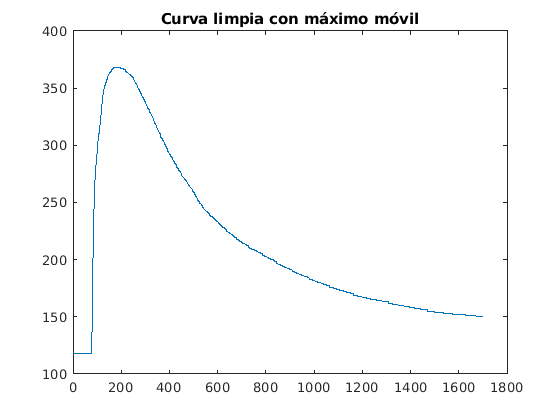

%Máximo móvil
RVB_data_movMax=movmax(RVB_data_Nans,6);

figure
plot(RVB_data_movMax)
title("Curva limpia con máximo móvil")

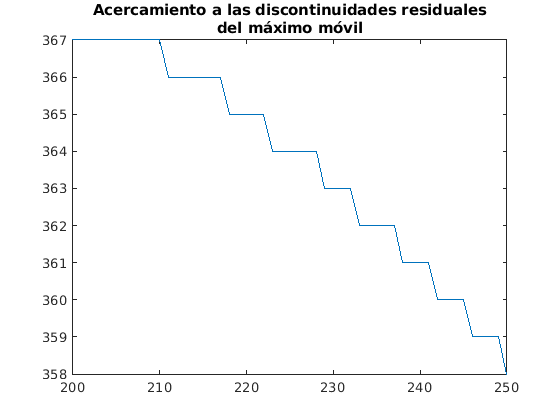


%Promedio móvil para suavizar la curva resultante del
%Máximo móvil
figure
plot(RVB_data_movMax)
xlim([200 250])
title(["Acercamiento a las discontinuidades residuales";"del máximo móvil"])

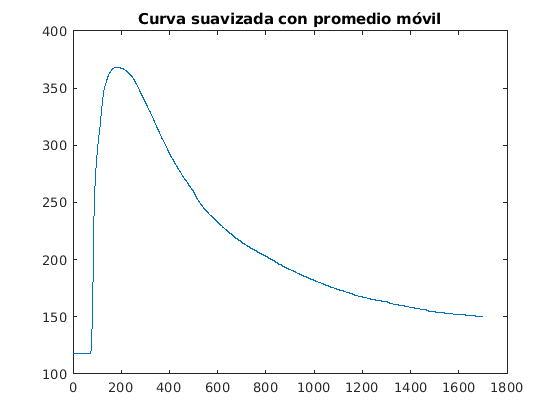


RVB_movmean=movmean(RVB_data_movMax,10);
figure
plot(RVB_movmean)
title("Curva suavizada con promedio móvil")

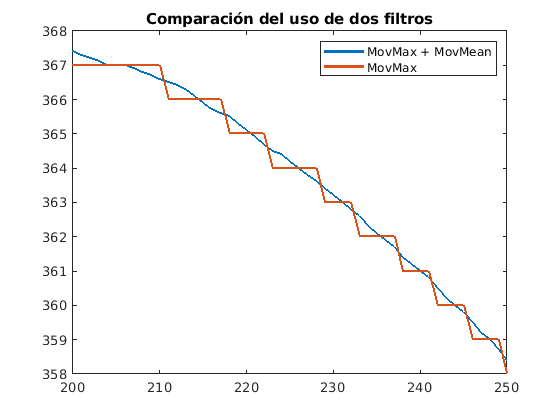


figure
plot([RVB_movmean RVB_data_movMax],'LineWidth',2)
xlim([200 250])
legend("MovMax + MovMean","MovMax" )
title("Comparación del uso de dos filtros")

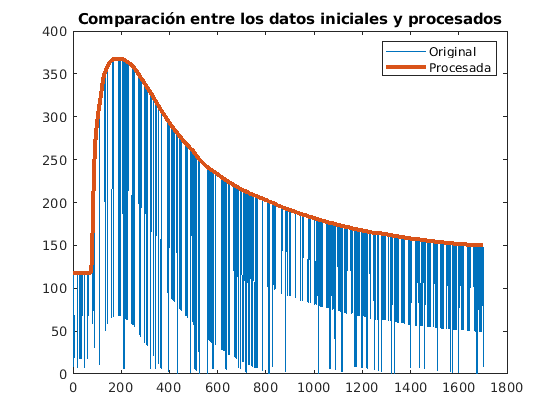


%Comparación del resultado final
figure
plot(RVB_data)
hold on
plot(RVB_movmean,'LineWidth',3)
hold off
legend("Original","Procesada" )
title("Comparación entre los datos iniciales y procesados")